%% train_iris_release.m
% Public-ready script for classifying Fisher's Iris dataset with a frozen
% NAR-style network (two fixed tanh FC blocks + softmax head).
%
% Dataset
% -------
% Fisher's Iris is bundled with MATLAB: `load fisheriris` provides:
%   - meas   : [150 x 4] numeric features (sepal length/width, petal length/width)
%   - species: [150 x 1] cellstr of class labels (setosa, versicolor, virginica)
%
% Usage
% -----
%   train_iris_release
%
% Notes
% -----
% * Requires: MATLAB R2023b+ and Deep Learning Toolbox.
% * Custom initializers: uses your original functions
%     customWeights1_git / customWeights2_git / customWeights3_git
%   Ensure these are on the MATLAB path (same folder or +package).
% * Plots: keeps the built-in training-progress window and adds post-hoc
%   result plots (confusion matrices and ROC if available).

%% -------------------- User-configurable section --------------------
WIDTH      = 16000;   % reduce (e.g., 1024) if memory-constrained
MAX_EPOCHS = 10000;
LR         = 0.01;
MINIBATCH  = 150;     % small dataset, one batch is fine

%% -------------------------- Main routine --------------------------
clearvars -except WIDTH MAX_EPOCHS LR MINIBATCH
close all; clc; rng(42,'twister');

% Load Fisher's Iris dataset
load fisheriris  % provides 'meas' and 'species'
labels = categorical(species);
X = meas';              % [4 x 150]

% Normalize features (zero mean, unit variance), scaled by 1/sqrt(C)
X = (1/sqrt(4)) * ((X - mean(X,2)) ./ std(X,0,2));

% Train/val/test split: 80/20 then 80/20 of train for val
numSamples = size(X,2);
cv1 = cvpartition(numSamples,'HoldOut',0.2);
XTrainFull = X(:, training(cv1));
YTrainFull = labels(training(cv1));
XTest  = X(:, test(cv1));
YTest  = labels(test(cv1));

cv2 = cvpartition(sum(training(cv1)),'HoldOut',0.2);
XTrain = XTrainFull(:, training(cv2));
YTrain = YTrainFull(training(cv2));
XVal   = XTrainFull(:, test(cv2));
YVal   = YTrainFull(test(cv2));

% Define network (two frozen FC tanh layers + softmax output)
% Initializers: your custom functions customWeights1/2/3
layers = [
    featureInputLayer(size(XTrain,1), Normalization='none')
    fullyConnectedLayer(WIDTH,'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights1_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(WIDTH,'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights2_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    tanhLayer
    fullyConnectedLayer(3, 'Name','output', ...
        'WeightLearnRateFactor',0, ...
        'WeightsInitializer',@customWeights3_git,'BiasL2Factor',0,'BiasInitializer','zeros')
    softmaxLayer];

net = dlnetwork(layers);

% Convert to dlarray
XTrain_dl = dlarray(single(XTrain), 'CB');
XVal_dl   = dlarray(single(XVal),   'CB');

% Training options (keep training-progress plot)
options = trainingOptions('adam', ...
    'MaxEpochs', MAX_EPOCHS, ...
    'Metrics', ["accuracy"], ...
    'MiniBatchSize', MINIBATCH, ...
    'InitialLearnRate', LR, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal_dl, YVal}, ...
    'Plots', 'training-progress', ...
    'Verbose', 0, ...
    'ValidationFrequency', 10);

[net, info] = trainnet(XTrain_dl, YTrain, net, 'crossentropy', options); %#ok<NASGU>


% Test evaluation
XTest_dl = dlarray(single(XTest), 'CB');
scores = predict(net, XTest_dl);         % 3 x N
[~, idx] = max(scores, [], 1);
predictedLabels = categorical(idx(:), 1:3, categories(YTrain));

acc = mean(predictedLabels == YTest);
fprintf('Test Accuracy: %.2f%%\n', 100*acc);

Test Accuracy: 100.00%


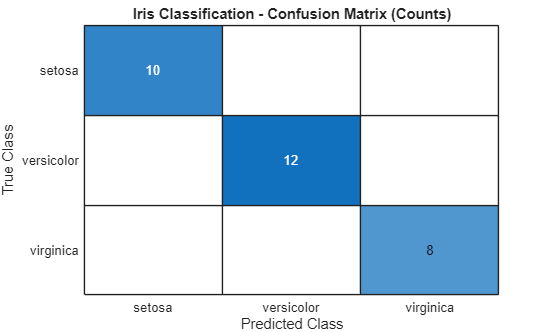


% Confusion matrix (counts)
figure('Name','Confusion Matrix (Counts)','Color','w');
confusionchart(YTest, predictedLabels);
title('Iris Classification - Confusion Matrix (Counts)');

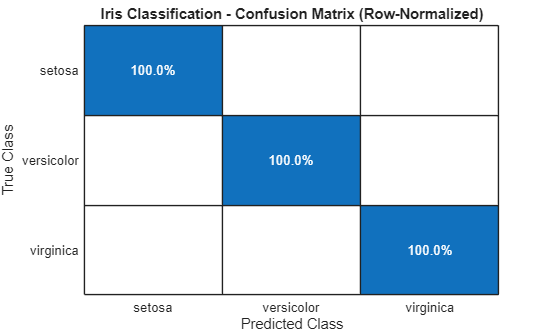


% Confusion matrix (row-normalized)
figure('Name','Confusion Matrix (Normalized)','Color','w');
confusionchart(YTest, predictedLabels,'Normalization','row-normalized');
title('Iris Classification - Confusion Matrix (Row-Normalized)');